%% Global variables

% Define baseline arm geometry
rho_outer_base = 0.06;
rho_inner_base = 0.01;
l_0 = 0.5;
N_segments = 4;

% Define load scenario
p = [60; 0; 60; 0];
Q = [0; -10; 0];
Q_frame = "World";

%% Create a no-taper arm
constant_arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_segments, rho_inner_base, rho_outer_base, l_0);
constant_arm.set_mechanics(BasicPolyBellowMechanics(l_0), [1, 4]);
constant_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2, 3]);
constant_arm.solve_equilibrium_gina(p, Q);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0017   -0.0018   -0.0114   -0.0294
    0.0000    0.0000    0.0001   -0.0001
    0.0936    0.0943    0.5618    1.3619


Plotter2D.plot_arm_series(constant_arm, axes(figure()));

%% Create a constant taper arm
rho_outer_tip = 0.04;
rho_inner_base = 0.02;
rho_inner_tip = 0.01;

full_constant_taper_arm = ArmSeriesFactory.tapered_2d_antagonist_arm( ...
    N_segments, rho_inner_base, rho_outer_base, rho_inner_tip, rho_outer_tip, l_0 ...
);
full_constant_taper_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2,3]);

full_constant_taper_arm.solve_equilibrium_gina(p, Q);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0004   -0.0012   -0.0031   -0.0096
    0.0000    0.0000    0.0000   -0.0001
    0.0198    0.0820    0.2326    0.8910


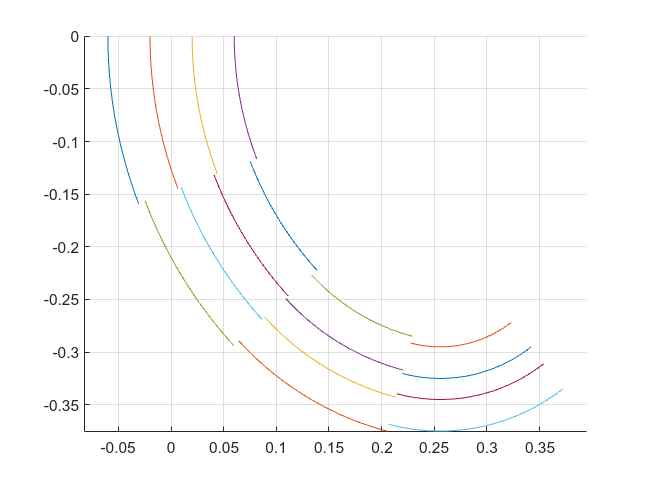

Plotter2D.plot_arm_series(full_constant_taper_arm, axes(figure()))

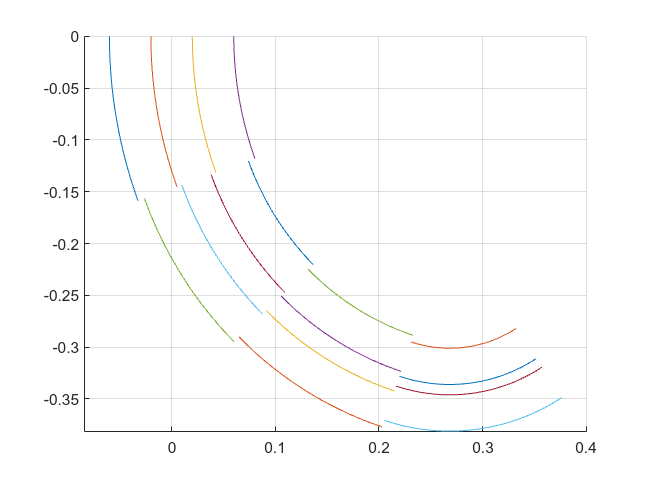

% Constant taper arm with straight center
%% Create a constant taper arm
% TODO: This is copy paste and will be refactored
r_outer_base = 0.06;
r_inner_base = 0.01;
rho_outer_tip = 0.04;
rho_inner_tip = 0.005;

outside_constant_taper_arm = ArmSeriesFactory.tapered_2d_antagonist_arm( ...
    N_segments, rho_inner_base, rho_outer_base, rho_inner_tip, rho_outer_tip, l_0 ...
);
outside_constant_taper_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2, 3]);

outside_constant_taper_arm.solve_equilibrium_gina(p, Q);
Plotter2D.plot_arm_series(outside_constant_taper_arm, axes(figure()))


No solution found.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance, but the vector of function values
is not near zero as measured by the value of the function tolerance.

<stopping criteria details>
Nonzero residual detected. Printing: 
   -0.0014   -0.0050   -0.0121   -0.0229
    0.0000    0.0001    0.0001   -0.0004
    0.1370    0.4512    1.0871    1.7862


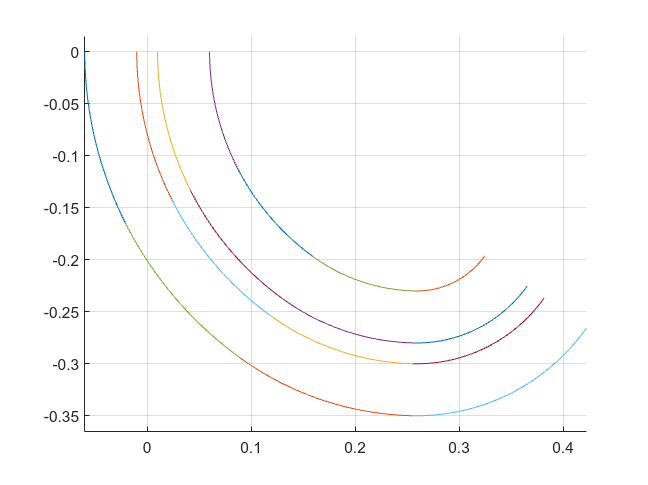

fzero residual is nonzero (> 0.01). Printing: 
   -0.0004   -0.0012   -0.0031   -0.0096
    0.0000    0.0000    0.0000   -0.0001
    0.0198    0.0820    0.2326    0.8910


fzero residual is nonzero (> 0.01). Printing: 
   -0.0005   -0.0009   -0.0042   -0.0084
    0.0000    0.0000    0.0001   -0.0001
    0.0440    0.1126    0.6098    1.2390


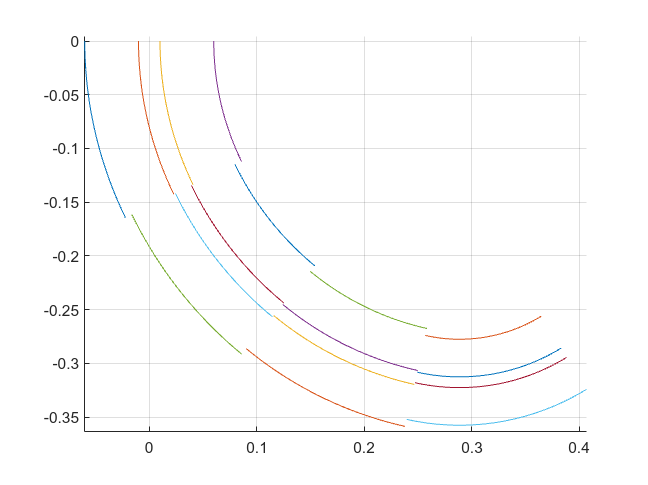

Q_design = [0; -10; 0];

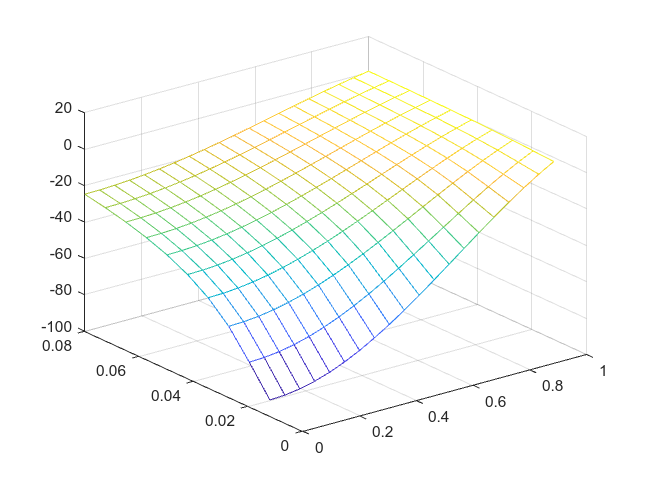


% Compute the force surface
N_arms = 10;
N_arm_segs = 20;

r_outer = linspace(0.012, 0.08, N_arms);
r_inner = 0.01;
l_0 = 0.5;

g_circ_right = [0.5; 0; 2.5];
mat_g_circ_right = repmat(g_circ_right, 1, N_arm_segs);

cell_arms = cell(1, N_arms);
mat_forces = zeros(4, N_arm_segs, N_arms);
for i = 1 : N_arms
    r_outer_i = r_outer(i);
    arm_i = ArmSeriesFactory.constant_2d_antagonist_arm(N_arm_segs, r_inner, r_outer_i, l_0);
    arm_i.g_circ_right = mat_g_circ_right;
    actuator_forces = lsqminnorm(arm_i.segments(1).mat_A, -arm_i.calc_external_reaction(Q_design));
    mat_forces(:, :, i) = actuator_forces;

    cell_arms{i} = arm_i;
end

s = linspace(0, 1, N_arm_segs);
[S, R] = meshgrid(s, r_outer);
figure()
F = reshape(mat_forces(4, :, :), N_arm_segs, N_arms)';
mesh(S, R, F)

% Simulate an actual tapered arm and plot its actuator forces on the taper
% surface

r_outer_base = 0.08;
r_outer_tip = 0.02;
rs_tapered = linspace(r_outer_base, r_outer_tip, N_arm_segs);
tapered_arm = ArmSeriesFactory.tapered_2d_antagonist_arm(N_arm_segs, r_inner, r_outer_base, r_inner, r_outer_tip, l_0);

reactions_tapered_arm = -tapered_arm.calc_external_reaction(Q_design, mat_g_circ_right);
F_tapered_arm = zeros(4, length(tapered_arm.segments));
for i = 1 : length(tapered_arm.segments)
    segment_i = tapered_arm.segments(i);
    F_tapered_arm(:, i) = lsqminnorm(segment_i.mat_A, reactions_tapered_arm(:, i));
end

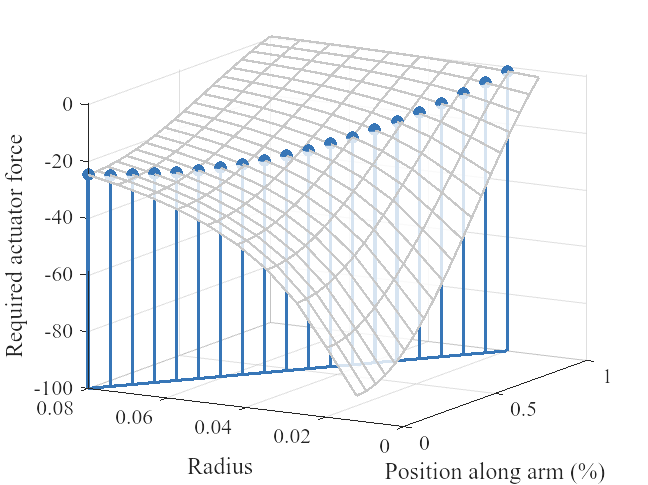

blue = [55, 118, 183] / 255;
purple = [158, 63, 165] / 255;
orange = [239, 161, 28] / 255;
darkgray = [200, 200, 200] / 255;

floor = -100;

axes(figure("Renderer", "painters"), "FontName", "Times", "FontSize", 14);
colormap("jet")
hold on
mesh(S, R, F, "FaceAlpha", 0.8, "LineWidth", 1.5, "EdgeColor", darkgray)
stm = stem3(s, rs_tapered, F_tapered_arm(4, :), "filled", "BaseValue", floor, "LineWidth", 2, "Color", blue);
plot3(s, rs_tapered, floor * ones(size(rs_tapered)), "Color", blue, "Linewidth", 2);
grid on
view(-60, 15)
xlabel("Position along arm (%)");
ylabel("Radius");
zlabel("Required actuator force");
set(gcf, "Renderer", "painters")

% Get radius-along-the-arm which traces the constant force contour,
% strating from the same base radius as the traditionally tapered arm.
force_at_base = F_tapered_arm(4, 1);
constant_force = contourc(s, r_outer, F, [force_at_base, force_at_base]);
constant_force = constant_force(:, 2:end);
constant_force = flip(constant_force, 2);
constant_force_radii_interp  = interp1(constant_force(1, :), constant_force(2, :), s);

s_nonnan = s(~isnan(constant_force_radii_interp));
constant_force_radii_interp_nonnan = constant_force_radii_interp(~isnan(constant_force_radii_interp));

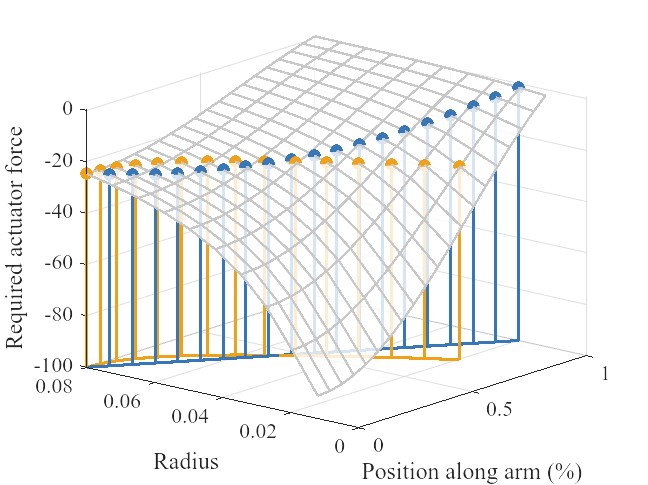

% Plot the new contour
axes(figure("Renderer", "painters"), "FontName", "Times", "FontSize", 14);
colormap("jet")
hold on
mesh(S, R, F, "FaceAlpha", 0.8, "LineWidth", 1.5, "EdgeColor", darkgray)
stem3(s, rs_tapered, F_tapered_arm(4, :), "filled", "BaseValue", floor, "LineWidth", 2, "Color", blue);
stem3( ...
    s, constant_force_radii_interp, force_at_base * ones(size(s)), ...
    "filled", "BaseValue", floor, "LineWidth", 2, "Color", orange ...
);
plot3(s, rs_tapered, floor * ones(size(rs_tapered)), "Color", blue, "Linewidth", 2);
plot3(s, constant_force_radii_interp, floor * ones(size(s)), "Color", orange, "Linewidth", 2)
grid on
view(-50, 20)
xlabel("Position along arm (%)");
ylabel("Radius");
zlabel("Required actuator force");
set(gcf, "Renderer", "painters")

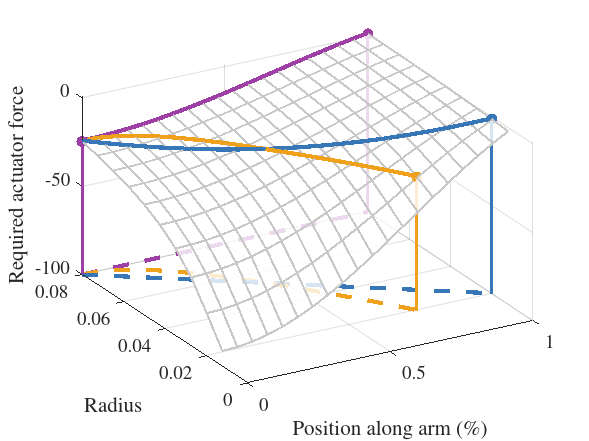

axes(figure("Renderer", "painters"), "FontName", "Times", "FontSize", 14);
hold on

linewidth = 3;

mesh(S, R, F, "FaceAlpha", 0.8, "LineWidth", 1.5, "EdgeColor", darkgray)
plot3(s, rs_tapered, F_tapered_arm(4, :) + 0.5, "LineWidth", linewidth, "Color", blue);
plot3( ...
    s, constant_force_radii_interp, force_at_base * ones(size(s)) + 0.5, "LineWidth", linewidth, "Color", orange ...
);
plot3(s, 0.08 * ones(size(s)), mat_forces(4, :, end) + 0.5, "Linewidth", linewidth, "Color", purple)

plot3(s, rs_tapered, floor * ones(size(rs_tapered)), "Color", blue, "Linewidth", linewidth, "Linestyle", "--");
plot3(s, constant_force_radii_interp, floor * ones(size(s)), "Color", orange, "Linewidth", linewidth, "Linestyle", "--")
plot3(s, 0.08 * ones(size(s)), floor * ones(size(s)), "Color", purple, "Linewidth", linewidth, "Linestyle", "--")

stem3(s([1, end]), rs_tapered([1, end]), F_tapered_arm(4, [1, end]), "filled", "BaseValue", floor, "LineWidth", 2, "Color", blue)
stem3(s_nonnan([1, end]), constant_force_radii_interp_nonnan([1, end]), force_at_base * [1, 1], "filled", "BaseValue", floor, "LineWidth", 2, "Color", orange)
stem3(s([1, end]), 0.08 * [1, 1], mat_forces(4, [1, end], end), "filled", "BaseValue", floor, "LineWidth", 2, "Color", purple)

grid on
%view(-50, 20)
view(-30, 35)
xlabel("Position along arm (%)");
ylabel("Radius");
zlabel("Required actuator force");
set(gcf, "Renderer", "painters")

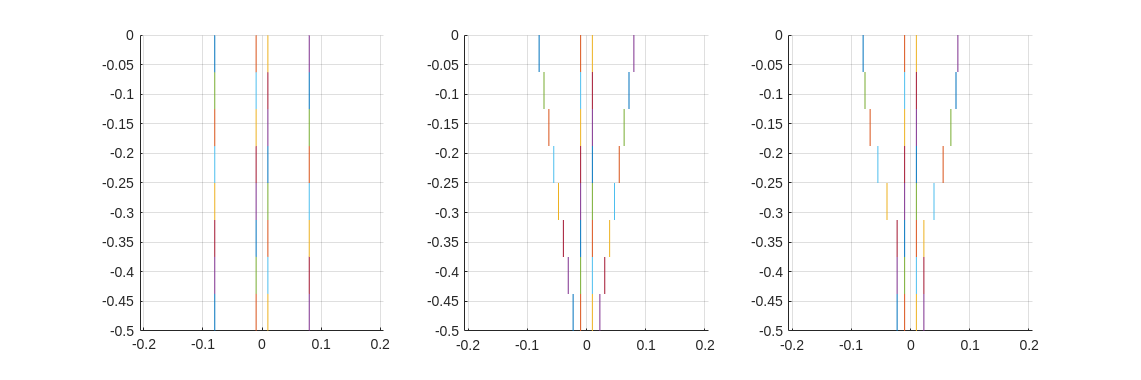

%% Create a varying taper arm based on the constant-force contour from above.
% Create list of radii from the constant-force contour
N_varying_taper_segs = 8;
s_varying_taper = linspace(0, 1, N_varying_taper_segs);
varying_taper_radii = interp1(constant_force(1, :), constant_force(2, :), s_varying_taper);
varying_taper_radii(isnan(varying_taper_radii)) = min(varying_taper_radii);

inner_radii = 0.01 * ones(size(varying_taper_radii));
varying_taper_arm = ArmSeriesFactory.varying_taper_2d_antagonist_arm(inner_radii, varying_taper_radii, l_0);

%% Create the comparable constant taper arm
rho_outer_base = 0.08;
rho_inner_base = 0.01;
rho_outer_tip = min(varying_taper_radii);
rho_inner_tip = 0.01;

full_constant_taper_arm = ArmSeriesFactory.tapered_2d_antagonist_arm( ...
    N_varying_taper_segs, rho_inner_base, rho_outer_base, rho_inner_tip, rho_outer_tip, l_0 ...
);
full_constant_taper_arm.set_mechanics(AnnealedGinaMuscleMechanics(l_0), [2,3]);

% Create a comparable no taper thick arm
constant_rho = 0.08;
full_constant_arm = ArmSeriesFactory.constant_2d_antagonist_arm(N_varying_taper_segs, rho_inner_base, constant_rho, l_0);

cell_arms = {full_constant_arm, full_constant_taper_arm, varying_taper_arm};

fig = figure("Position", [0, 0, 1500, 500]);
compare_arms(cell_arms, [0; 0; 0; 0], [0; 0; 0], fig)

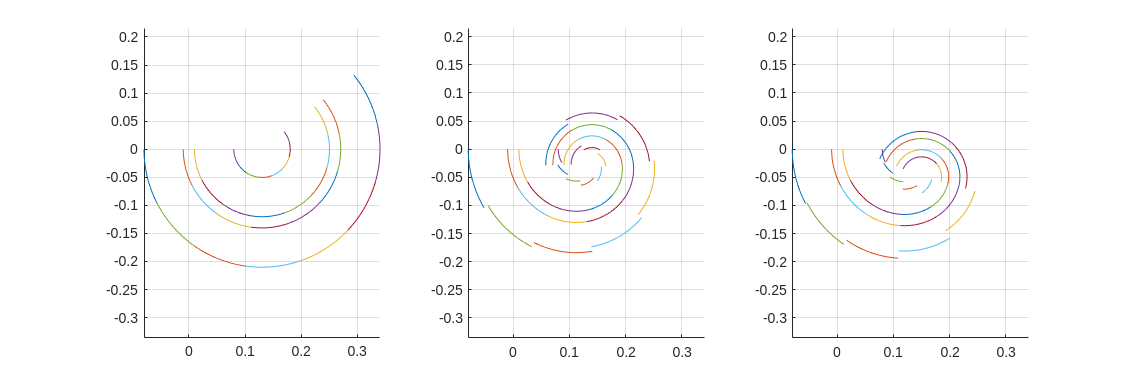

fzero residual is nonzero (> 0.01). Printing: 
   -0.0649   -0.0649   -0.0649   -0.0649   -0.0649   -0.0649   -0.0649   -0.0649
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    4.3470    4.3470    4.3470    4.3470    4.3470    4.3470    4.3470    4.3470
fzero residual is nonzero (> 0.01). Printing: 
   -0.0718   -0.0514   -0.0423   -0.0342   -0.0268   -0.0201   -0.0602   -0.0087
   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    3.5632    3.2225    2.8752    2.5173    2.1416    1.7354    1.2834    0.8217
fzero residual is nonzero (> 0.01). Printing: 
   -0.0649   -0.0613   -0.0512   -0.0378   -0.0238   -0.0103   -0.0103   -0.0103
    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    4.3470    4.1856    3.7119    2.9959    2.0932    0.9397    0.9397    0.9397


Q = [0; 0; 0];

fig = figure();
set(fig, "Position", [0, 0, 1500, 500]);
compare_arms(cell_arms, p, Q, fig);

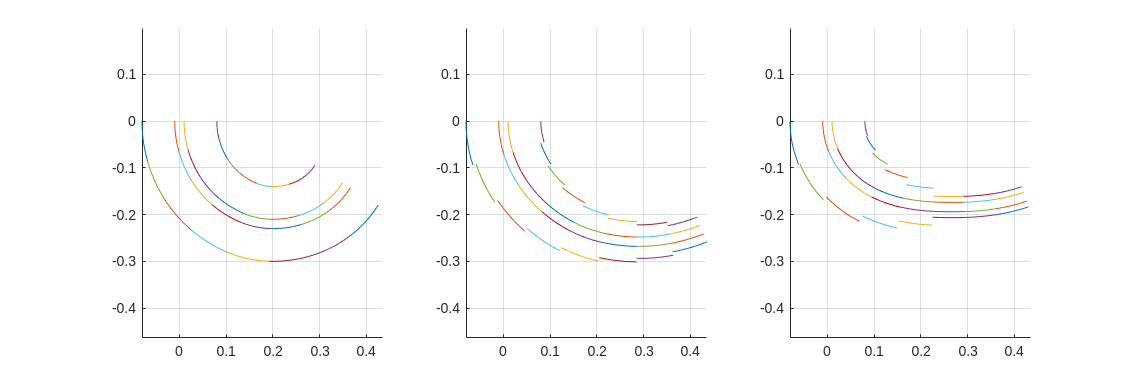

fzero residual is nonzero (> 0.01). Printing: 
   -0.0142   -0.0154   -0.0178   -0.0244   -0.0308   -0.0405   -0.0500   -0.0589
    0.0002    0.0003    0.0004    0.0004    0.0002   -0.0002   -0.0008   -0.0018
    1.2972    1.3685    1.4893    2.0218    2.2227    3.1194    3.6783    4.1750


Q = [0; -10; 0];
fig = figure();
set(fig, "Position", [0, 0, 1500, 500]);
compare_arms(cell_arms, p, Q, fig);

While the tapered arm has a more useful workspace under a moderate amount of load, under an even heavier load the tapered arm ultimately still deforms more.

In this vein, it appears that taper trades off total bending stiffness of the arm for a more useful effective workspace.

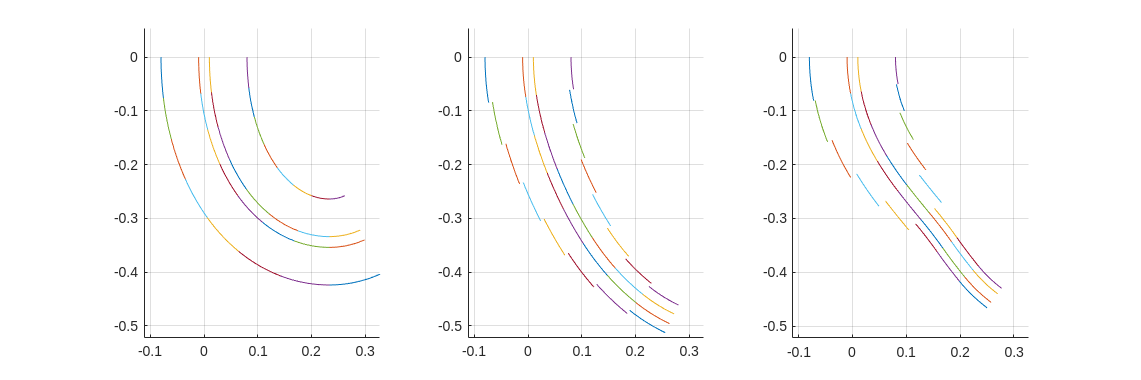

Q = [0; -20; 0];
fig = figure();
set(fig, "Position", [0, 0, 1500, 500]);
compare_arms(cell_arms, p, Q, fig);

function compare_arms(cell_arms, pressures, loads, fig)
    % TODO: Wrap everything below in a "for i_loads in size(loads, 2)"

    tl = tiledlayout(fig, 1, length(cell_arms));
    for i_arm = 1 : length(cell_arms)
        arm_i = cell_arms{i_arm};
        arm_i.solve_equilibrium_gina(pressures, loads);

        ax = nexttile;
        Plotter2D.plot_arm_series(arm_i, ax);
        grid on
    end
    linkaxes(tl.Children);
end